## Prep data

load('training_set_5_psth.mat','input_training','output_training')
nullSamples = (output_training < 0.001);
X = input_training(~nullSamples,:);
Y = output_training(~nullSamples);
trainBatch = 0.9;

m = size(Xtrain,1)

m = 29525

m_train = randsample(m,round(m*trainBatch));
Xtrain = X(m_train,:);
Ytrain = Y(m_train,:);
Xtest = X;
Xtest(m_train,:) = [];
Ytest = Y;
Ytest(m_train,:) = [];

## Create Layers

% define main path
mu = 0.5;
a = mu - 0.005;
b = mu + 0.005;

mainPath = [
    featureInputLayer(4,'Name','input')
    
    additionLayer(2,'Name','add_In_Inh')
    reluLayer('Name','R_out')
    
%     fullyConnectedLayer(1,'Name','C','Weights',a + (b-a).*rand(1,4))
    FCpositiveWeights(4,1,'C',a + (b-a).*rand(1,4))
    

    regressionLayer('Name','output')
    ]

mainPath =   5×1 Layer array with layers:

     1   'input'        Feature Input       4 features
     2   'add_In_Inh'   Addition            Element-wise addition of 2 inputs
     3   'R_out'        ReLU                ReLU
     4   'C'            FCpositiveWeights   Fully connected, positive-weighted layer
     5   'output'       Regression Output   mean-squared-error


inhPath = [
%     negationLayer('negation')
    
%     fullyConnectedLayer(4,'Name','R','Weights',a + (b-a).*rand(4))
%     FCpositiveWeights(4,4,'R',a + (b-a).*rand(4))
    FCInhibitoryInput(4,4,'I->R',a + (b-a).*rand(4))
    ]

inhPath =   FCInhibitoryInput with properties:

       Name: 'I->R'

   Learnable Parameters
    Weights: [4×4 double]
       Bias: [4×1 double]

  Show all properties


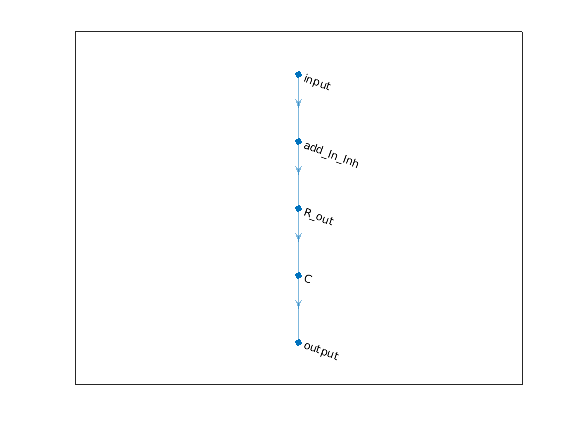


lgraph = layerGraph(mainPath);
plot(lgraph);


% Add inh path to main path
lgraph = addLayers(lgraph,inhPath)

lgraph =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [4×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


lgraph = connectLayers(lgraph,'input','I->R')

lgraph =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


lgraph = connectLayers(lgraph,'I->R','add_In_Inh/in2')

lgraph =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}



plot(lgraph)


## Analyze network

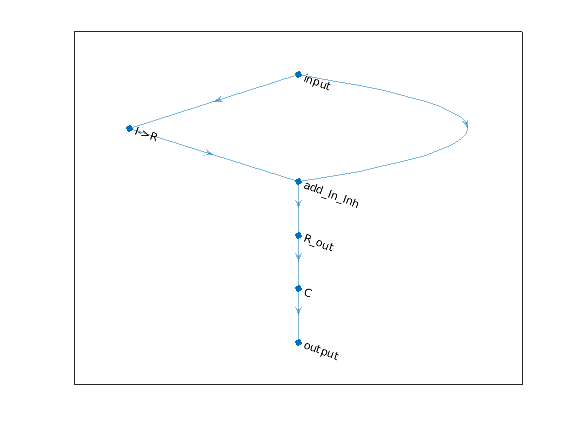

analyzeNetwork(lgraph)

## Train network

maxEpochs = 20;
miniBatchSize = 512;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'ValidationData',{Xtest,Ytest}, ...
    'ValidationFrequency',300, ...
    'Verbose',0, ...
    'Plots','training-progress',...
    'ExecutionEnvironment', 'auto');

net = trainNetwork(Xtrain,Ytrain,lgraph,options);

## Check network weights

net.Layers

ans =   6×1 Layer array with layers:

     1   'input'        Feature Input       4 features
     2   'add_In_Inh'   Addition            Element-wise addition of 2 inputs
     3   'R_out'        ReLU                ReLU
     4   'C'            FCpositiveWeights   Fully connected, positive-weighted layer
     5   'output'       Regression Output   mean-squared-error with response 'Response'
     6   'I->R'         FCInhibitoryInput   Fully connected, layer. Input is negated to simulate inhibition


IR_LayerIdx = 6  %choose appropriate index to get the desired layer

IR_LayerIdx = 6

net.Layers(IR_LayerIdx).Weights

ans = 4×4 single matrix
    0.2543    0.2024    0.1899   -0.0605
    0.5892    0.0245   -0.0798    0.6758
    0.6485   -0.1235    0.0099    0.7870
   -0.1215    0.5301    0.5186    0.0756


Train Network again with rectified weights

lgraph2 =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     InputNames: {'input'}
    OutputNames: {'output'}


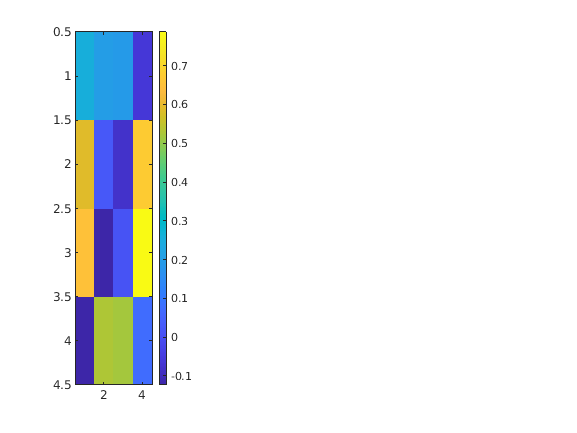

mu = 0.01;
a = mu - 0.005;
b = mu + 0.005;
for i = 1:1
    subplot(1,3,i);
    imagesc(net.Layers(IR_LayerIdx).Weights); colorbar;
    
    % recfity weights
    temp_net = net.saveobj;
    temp_net.Layers(4).Weights = abs(temp_net.Layers(4).Weights);
%     temp_net.Layers(4).Weights = (temp_net.Layers(4).Weights-0.5)*0.5+0.5;
    temp_net.Layers(4).Bias = 0;
    temp_net.Layers(IR_LayerIdx).Weights = abs(temp_net.Layers(IR_LayerIdx).Weights);
%     temp_net.Layers(IR_LayerIdx).Weights = (temp_net.Layers(IR_LayerIdx).Weights-0.5)*0.5+0.5
    temp_net.Layers(IR_LayerIdx).Bias = [0 0 0 0]';
    
    % train again with rectified weights
    rectified_net = net.loadobj(temp_net);
    lgraph2 = layerGraph(rectified_net)
    net = trainNetwork(Xtrain,Ytrain,lgraph2,options);
end

Analyze the weights of the trained network

net.Layers(4)

ans =   FCpositiveWeights with properties:

       Name: 'C'

   Learnable Parameters
    Weights: [0.8269 1.2552 1.2359 1.0533]
       Bias: -0.0543

  Show all properties


net.Layers(IR_LayerIdx).Weights

ans = 4×4 single matrix
    0.1250    0.0532   -0.0812   -0.1232
    0.6927   -0.2417   -0.1882    0.7897
    0.7159   -0.2085   -0.2164    0.0366
   -0.2658    0.4963    0.7850   -0.0324


net.Layers(IR_LayerIdx).Bias

ans = 4×1 single column vector
   -0.0160
   -0.0452
   -0.0471
    0.0155


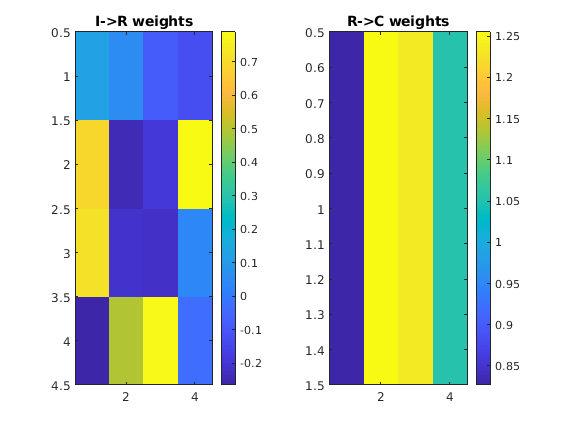


figure;
subplot(1,2,1)
imagesc(net.Layers(IR_LayerIdx).Weights); title('I->R weights')
colorbar

subplot(1,2,2)
imagesc(net.Layers(4).Weights); title('R->C weights')
colorbar

Visualize outputs

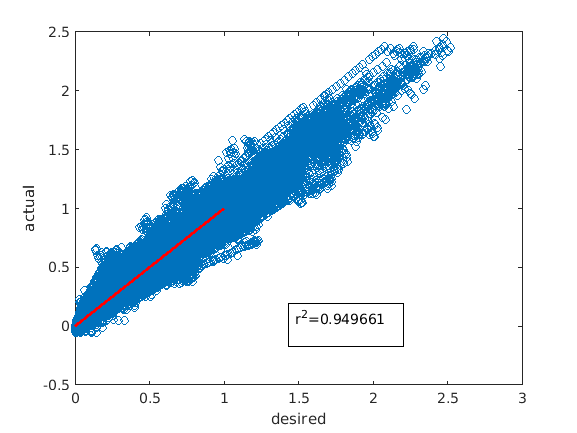

out = predict(net,Xtrain);

r2 = corrcoef(out,Ytrain);
figure
plot(Ytrain,out,'o'); hold on;
plot(0:0.01:1,0:0.01:1,'r','linewidth',2)
xlabel('desired')
ylabel('actual')
annotation("textbox",[0.5,0.2 0.2 0.1],'string',sprintf('r^2=%f',r2(1,2)))